## Check closed-loop step response carried out with arduino

The arduino sketch record_data_for_matlab.ino prints 

- the time in milliseconds, 

- the angle phi in degrees,

- the angular velocity omega in degrees per second,

- the integrated error (in degrees, because it is only summed), 

- the input u (in degrees).

The next code block reads this data, extracts t and phi, and plots phi as a function of t. 

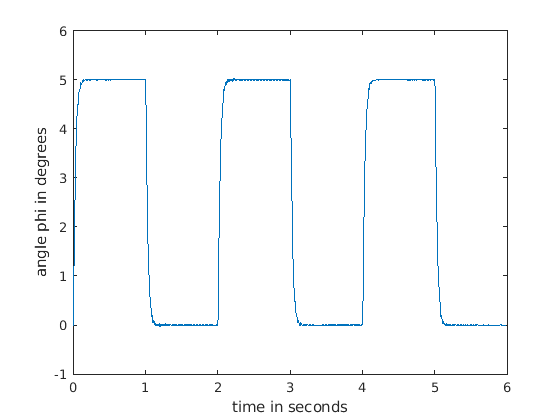

close all; 
clear all;
filename_step_response_data= "../arduino/closed-loop-step-response/record_data_for_matlab/data_for_matlab.txt";
step_response_data= readtable(filename_step_response_data);

tdata= step_response_data{:, 1}; 
tdata= tdata- tdata(1); % subtract t0
tdata= tdata/1e6; % turn milliseconds into seconds
phidata= step_response_data{:,2};

plot(tdata, phidata);
ylabel("angle phi in degrees"); 
xlabel("time in seconds"); 